# 1D optimisation of droplet center

#### To generate optimisation procedure for the *(center of the)* initial droplet location

- Select variables for droplet and chose Target Shape

- Plot initial droplet shape based on chosen `x0`

- Use optimisation prosidure to find bes possition of droplet

**Looping erro**

- Set grid size to small value:` xMax = 10`

- If  |`x - x0`|` ~= x0`,   where   `x ≠ x0`

- Then `x_sol = x0 ~≠ x`

**Solution**

- make` xMax >> |x - x0|`

**Gradient distribution erro**

- If `|x - x0| `is too large,` TolX `is met 

- but` |x - x0| `is not close to zero

**Solution**

- Modifi ` costEvaluation...`

- Possibly to account for central difference

**or**

- Just have` x0 `sufficiently close to` x`

- `x0 `should be within targetshape rejion

clear; clc;

## **1) **

**Set some values**

y0 = .1084434390; % Raise droplet profile...
N = 800; % # sample points
A = 21; % Magnitude/Amplitude of droplet
c1 = 0.001264379882813;
c2 = 0.016807519531250;

xMax = 80; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
var = [A;N;k;y0;c1;c2]; 

% Set time span
tfinal = 10^5; % final time >> 1
tSpan = [1e-6 tfinal]; 

% Possition / Shift
x0 = 8;
% x0 = 2;


% Condition
conds0 = x0;

% Creating test matrix to soolve ODE
D1 = full(gallery('tridiag',N,-1,0,1));
D1(N,1)=1;D1(1,N)=-1;
D1 = D1/(2*dx);
D1 = sparse(D1); % D1
D2 = full(gallery('tridiag',N,1,-2,1));
D2(N,1)=1;D2(1,N)=1;
D2 = D2/dx^2;
D2 = sparse(D2); % D2

**Target Shape **`h_target`

h_target = 0.1*ones(size(X));
h_target(2.5 - X.^2/12>0.1) = 2.5 - X(2.5 - X.^2/12>0.1).^2/12;
% Target shape is a parabola, not achievable

## **2) **

**Initial droplet centered around **`x0`

h0 = hFinal(conds0,X,var,D1,D2,tSpan);
H0 = deval(h0,tfinal); 

## **3)**

**Solution**

% Vertical/Function tolerance: 1e-1
% Horizontal tolerance: 1e-1
options = optimset('Display','iter','TolFun',1e-1,'TolX',1e-1,'MaxFunEvals',4*60,'MaxIter',4*50);

% Generate an object/function to be optimise
myObjective_Possition = @(conds) costEvaluation(conds,X,var,D1,D2,tSpan,tfinal,h_target);
% in this case we have a cost function

figure;

plot(X,h_target,'k:','linewidth',2);
title('2-D profile of droplet')
xlabel('x')
ylabel('u(x)')
hold on
plot(X,H0,'*r');
xlim([-20 50])
ylim([0 3]);
grid on

% Solution of best center point: x_sol
[conds_Sol,fval,exitflag,output,history] = myproblem(myObjective_Possition,conds0);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          162.731         
     1            2          162.731         initial simplex
     2            4          154.208         expand
     3            6           131.29         expand
     4            8          66.1074         expand
     5           10          26.8851         reflect
     6           12          26.8851         contract inside
     7           14          16.4244         contract inside
     8           16          16.4244         contract inside
     9           18          16.4244         contract outside
    10           20          16.4244         contract inside
    11           23          16.4244         shrink
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 



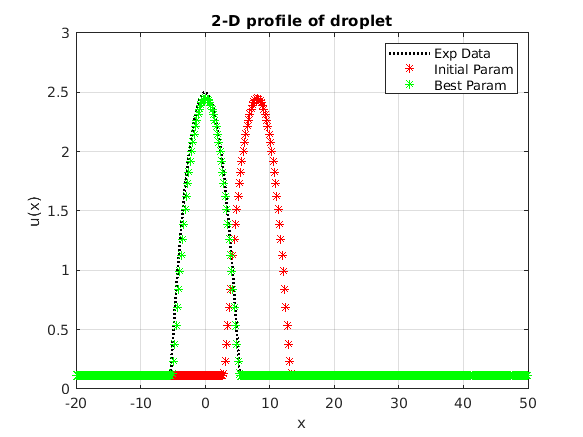


% resulting portfolio
h_Sol = hFinal(conds_Sol,X,var,D1,D2,tSpan);

% resulting final profile (at t = tfinal)
H_Sol = deval(h_Sol,tfinal);

plot(X,H_Sol,'*g')
legend('Exp Data','Initial Param','Best Param');
hold off


% history

% figure;
% grid on
% 
n = size(history);
n = n(1);
% m = size(H_Sol);
% m = m(1);
% p = ones(n,m);
% for i = 1:n
%     p(i,:)=deval(hFinal(history(i,:),X,var,D1,D2,tSpan),tfinal);
% end
% plot(X,p)
% grid on

dataH = abs(history(1:8,1))';

Error using interp1>reshapeAndSortXandV (line 424)
X and V must be of the same length.

Error in interp1 (line 93)
    [X,V,orig_size_v] = reshapeAndSortXandV(varargin{1},varargin{2});

dataHi = abs(history(:,1))';

lineH = 1:1:8;
[p,S,mu] = polyfit(lineH,dataH,1);
[pH,delta] = polyval(p,lineH,S,mu);

lineHi = 1:1:n;

xi = linspace(1, 8, 100); 
yi = interp1(lineH, dataHi, xi, 'spline', 'extrap');

figure;
hold on
plot(lineH,pH,'-',...
    'Color',[1 0 0],...
    'LineWidth',2);
plot(lineH,pH-1.4*delta,'m--');
plot(lineH,pH+1.4*delta,'m--');
plot(lineH,dataH,'o',...
    'MarkerSize',8,...
    'MarkerEdgeColor',[0 1 0],...
    'MarkerFaceColor',[1 1 0],...
    'LineWidth',1);
title('Iterative evolution of distance  \Delta(x_n) = | x - x_n|');
ylabel('\Delta(x_n)');
xlabel('x_n');
legend('Line of Best Fit','+ \Delta','- \Delta','\Delta(x_n)');
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'off';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
xlim([1 8]);
ylim([0 x0+1]);
hold off


figure;
hold on
plot(xi, yi, '--r');
plot(lineH,dataH,'o',...
    'MarkerSize',8,...
    'MarkerEdgeColor',[0 1 0],...
    'MarkerFaceColor',[1 1 0],...
    'LineWidth',1);
title('Iterative evolution of distance  \Delta(x_n) = | x - x_n|');
ylabel('\Delta(x_n)');
xlabel('x_n');
legend('Line of Best Fit','\Delta(x_n)');
ax = gca;
ax.GridLineStyle = '--';
ax.XGrid = 'on';
ax.YGrid = 'off';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
xlim([1 8]);
ylim([0 x0+1]);
hold off

% figure;
% % subplot(4,1,2);
% hold on 
% % plot(lineH,);
% semilogx(dataH,'o');
% % semilogx(pH,'-');
% % scatter(lineH,dataH);
% xlim([0 7]);
% ylim([0 x0+1]);
% grid on
% hold off

we see a faily straight line for the first 6 iterations  with a logspace x (iterations) axis